%------------------------------------------------------------------------
%Load the data
%This is when your NetCDF file is kept
ncdir='/Users/lilly/Desktop/Dropbox/NetCDF/';
filename='BetaEddyOne.nc';

%loading in data
lato=ncread([ncdir filename],'latitude');
f0=abs(corfreq(lato))/3600; %rad/s

x=ncread([ncdir filename],'x')/1000;%store distances in km
y=ncread([ncdir filename],'y')/1000;%store distances in km
ssh=squeeze(ncread([ncdir filename],'ssh'))*100;%store ssh in cm
u=squeeze(ncread([ncdir filename],'u'))*100;%store velocities in cm/s
v=squeeze(ncread([ncdir filename],'v'))*100;%store velocities in cm/s

%vorticity, shear strain, and normal strain, nondimensionalized by f0
zeta=squeeze(ncread([ncdir filename],'zeta'))/f0;
sigma=squeeze(ncread([ncdir filename],'sigma'))/f0;
nu=squeeze(ncread([ncdir filename],'nu'))/f0;
 
drifter_x=ncread([ncdir filename],'drifter_x')'/1000;%in km
drifter_y=ncread([ncdir filename],'drifter_y')'/1000;%in km 
drifter_u=ncread([ncdir filename],'drifter_u')'*100;%in cm/s
drifter_v=ncread([ncdir filename],'drifter_v')'*100;%in cm/s
%drifter_zeta=ncread([ncdir filename],'drifter_zeta')'./f0;
drifter_t=vrep([1:size(drifter_x,1)]',size(drifter_x,2),2);%time for drifters
%------------------------------------------------------------------------

Next we compute the eddy center location and largest instantaneous closed streamline based on the extrema of sea surface height.  

However, the eddy-centered coordinates formed in this way are centered on the extrema of the streamfunction relative to the Earth, not the streamfunction relative to the eddy.  The center of the latter will therefore not be at the origin.  To address this, we re-iterate the computation of the eddy frame streamfunction based on the location of its center, leading to a refinement of the eddy frame streamfunction.

%Compute eddy center location based on extremum of sea surface height 
%The "E" here stands for Earth
[xoE,yoE]=eddyCenterFromField(x,y,ssh,0.9,method="timesMax");
[xpE,ypE,sshE]=fieldInEddyFrame(x,y,xoE,yoE,300,ssh);

uoE=vdiff(xoE,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s
voE=vdiff(yoE,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s

[psipE,psiE,psifE] = eddyFrameStreamFunction(1000*xpE,1000*ypE,sshE/100,uoE/100,voE/100,f0);

tic;
[xpcE,ypcE,levels,index]=largestClosedStreamLine(xpE,ypE,psipE/1000,0.25);
toc

Elapsed time is 17.473444 seconds.


xcE=celladd(xpcE,xoE);%put these contours back in the Earth frame
ycE=celladd(ypcE,yoE);

%finally, mark particles as inside or outside trapping region 
%isTrapped=isParticleEnclosed(drifter_x,drifter_y,xc,yc);

%Compute eddy center location based on streamfunction in the eddy frame
%The "e" here stands for eddy

[xoe,yoe]=eddyCenterFromField(xpE,ypE,psipE,0.9,method="timesMax");
[xpe,ype,sshe]=fieldInEddyFrame(x,y,xoE+xoe,yoE+yoe,300,ssh);

uoe=vdiff(xoE+xoe,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s
voe=vdiff(yoE+yoe,1,'endpoint')*100*1000/(24*3600);%km/day to cm/s

[psipe,psie,psife] = eddyFrameStreamFunction(1000*xpe,1000*ype,sshe/100,uoe/100,voe/100,f0);

tic;
[xpce,ypce,levels,index]=largestClosedStreamLine(xpe,ype,psipe/1000,0.25);
toc

Elapsed time is 18.422593 seconds.


xce=celladd(xpce,xoE+xoe);%put these contours back in the Earth frame
yce=celladd(ypce,yoE+yoe);

%have we converged?
[xo_delta,yo_delta]=eddyCenterFromField(xpe,ype,psipe,0.9,method="timesMax");

%for comparison, eddy center from vorticity
[xoZ,yoZ]=eddyCenterFromField(x,y,zeta,0.9,method="timesMin");

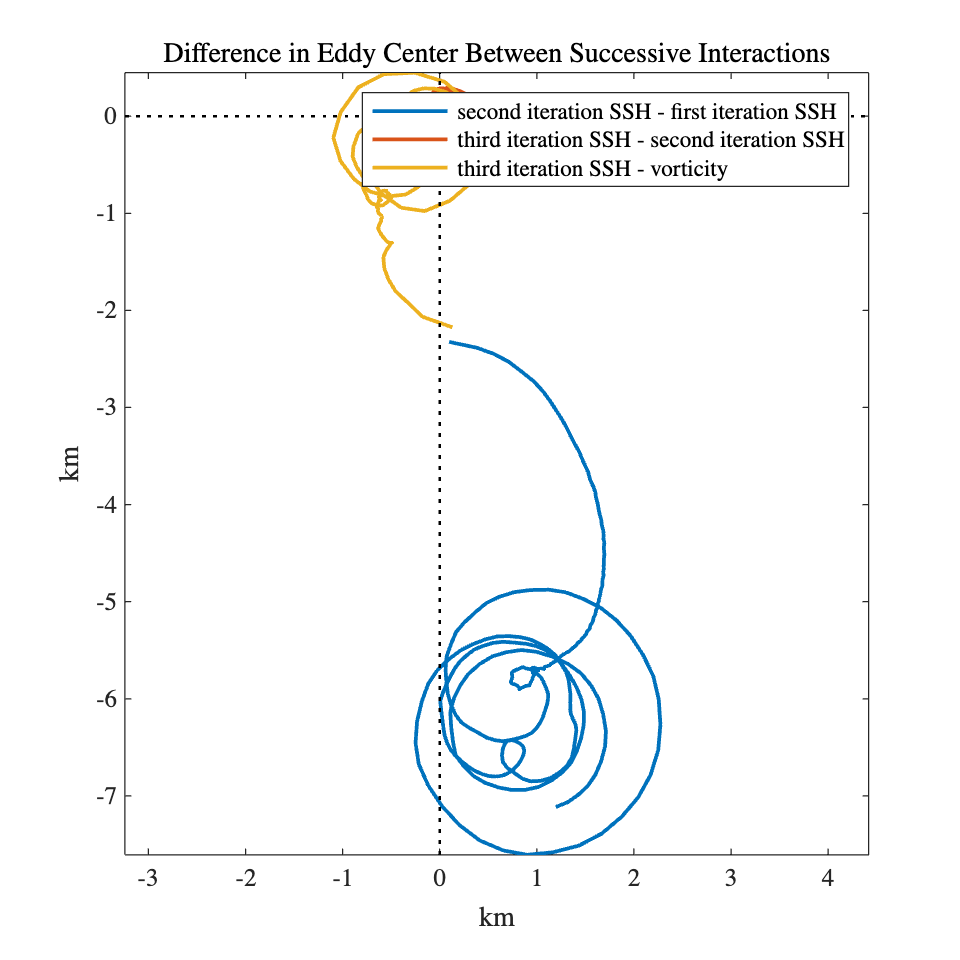

hf = figure();
hf.Position(3:4) = [1200, 1200];
hl=plot([xoe xo_delta xo_delta+xoe+xoE-xoZ],[yoe yo_delta yo_delta+yoe+yoE-yoZ],linewidth=1.5);axis equal
hlines(0,'k:'),vlines(0,'k:')
title('Difference in Eddy Center Between Successive Interactions')
xlabel('km'),ylabel('km')
legend(hl,'second iteration SSH - first iteration SSH','third iteration SSH - second iteration SSH','third iteration SSH - vorticity')

%sqrt(mean(xoe.^2+yoe.^2)) %5.8 km
%sqrt(mean(xo_delta.^2+yo_delta.^2)) %0.19 km

This shows that a third iteration leads to only a minor refinement of the eddy center location (0.2 km vs 5.8 km RMS error), so we will use the second iteration.

Note that this does change the estimated trapping slightly so we should should use the trapping contours based on the iterated definition. 

Also note that the iterated SSH center is close to the vorticity center. 

This next figure confirms that the eddy-centered streamfunction is indeed centered on the origin of the eddy frame after the second iteration, but not the first.

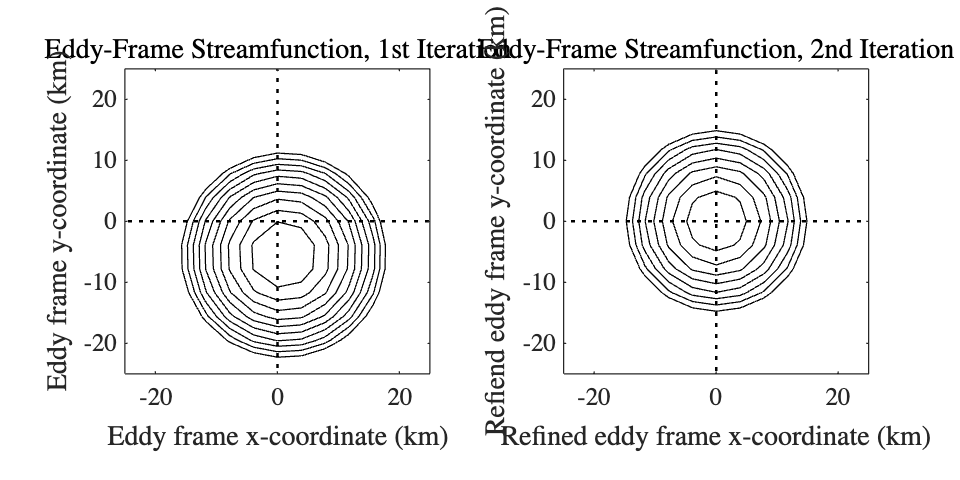

hf = figure();
hf.Position(3:4) = [1200, 600];

tiledlayout(1,2)

nexttile
contour(xpE,ypE,vmean(psipE,3)'/1000,[20:.1:30],'k'),axis equal
hlines(0,'k:'),vlines(0,'k:')
axis([-25 25 -25 25])
title('Eddy-Frame Streamfunction, 1st Iteration')
xlabel('Eddy frame x-coordinate (km)')
ylabel('Eddy frame y-coordinate (km)')

nexttile
contour(xpe,ype,vmean(psipe,3)'/1000,[20:.1:30],'k'),axis equal
hlines(0,'k:'),vlines(0,'k:')
axis([-25 25 -25 25])
title('Eddy-Frame Streamfunction, 2nd Iteration')
xlabel('Refined eddy frame x-coordinate (km)')
ylabel('Refiend eddy frame y-coordinate (km)')

Going forward, we keep in mind that there are **two **eddy-centered frames, depending on how we define the eddy center. 

Now we are ready to look at the radial statistics.  We will compare the earth-fixed streamfunction in the frame centered on the extremum of the earth-fixed streamfunction, and the eddy-fixed streamfunction in the frame centered its extremum after two iterations.

Here is what these looks like in the time average.

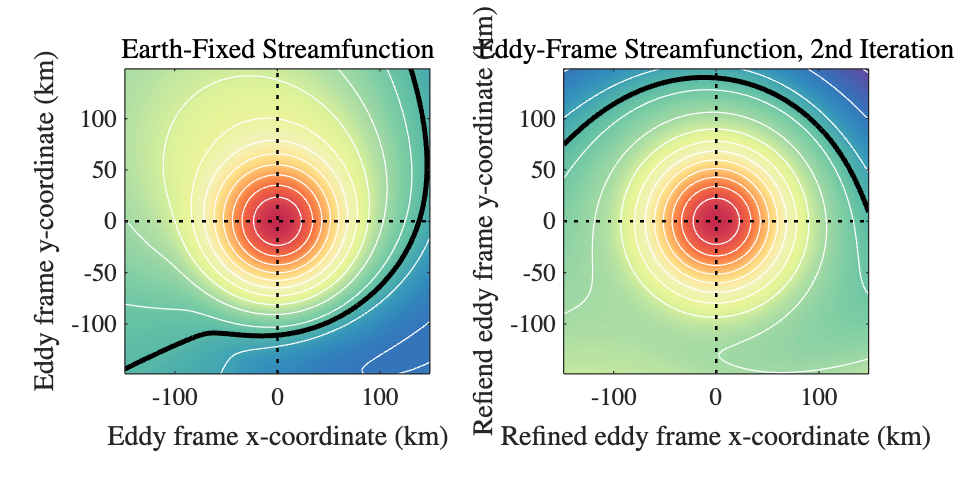

hf = figure();
hf.Position(3:4) = [1200, 600];

tiledlayout(1,2)

nexttile
contourf(xpE,ypE,vmean(psiE,3)'/1000,200),axis equal,nocontours,hold on
contour(xpE,ypE,vmean(psiE,3)'/1000,[-5:2:30],'w')
contour(xpE,ypE,vmean(psiE,3)'/1000,[0 0 ],'k','linewidth',2)
hlines(0,'k:'),vlines(0,'k:'),clim([-5 22.5])
%axis([-25 25 -25 25])
title('Earth-Fixed Streamfunction')
xlabel('Eddy frame x-coordinate (km)')
ylabel('Eddy frame y-coordinate (km)')

nexttile
contourf(xpe,ype,vmean(psipe,3)'/1000,200),axis equal,nocontours,hold on
contour(xpe,ype,vmean(psipe,3)'/1000,[-5:2:30],'w')
contour(xpe,ype,vmean(psipe,3)'/1000,[0 0 ],'k','linewidth',2)
hlines(0,'k:'),vlines(0,'k:'),clim([-5 22.5])
title('Eddy-Frame Streamfunction, 2nd Iteration')
xlabel('Refined eddy frame x-coordinate (km)')
ylabel('Refiend eddy frame y-coordinate (km)')

Now let's look at their radial statistics.

[mzEa,rmid,numzEa,stdz1Ea,stdz2Ea] = radialStatisticsFromField(xpE,ypE,psiE/1000,firstAverage="azimuthal");
[mzEt,~,numzEt,stdz1Et,stdz2Et] = radialStatisticsFromField(xpE,ypE,psiE/1000,firstAverage="temporal");
[mzea,~,numzea,stdz1ea,stdz2ea] = radialStatisticsFromField(xpe,ype,psipe/1000,firstAverage="azimuthal");
[mzet,~,numzet,stdz1et,stdz2et] = radialStatisticsFromField(xpe,ype,psipe/1000,firstAverage="temporal");

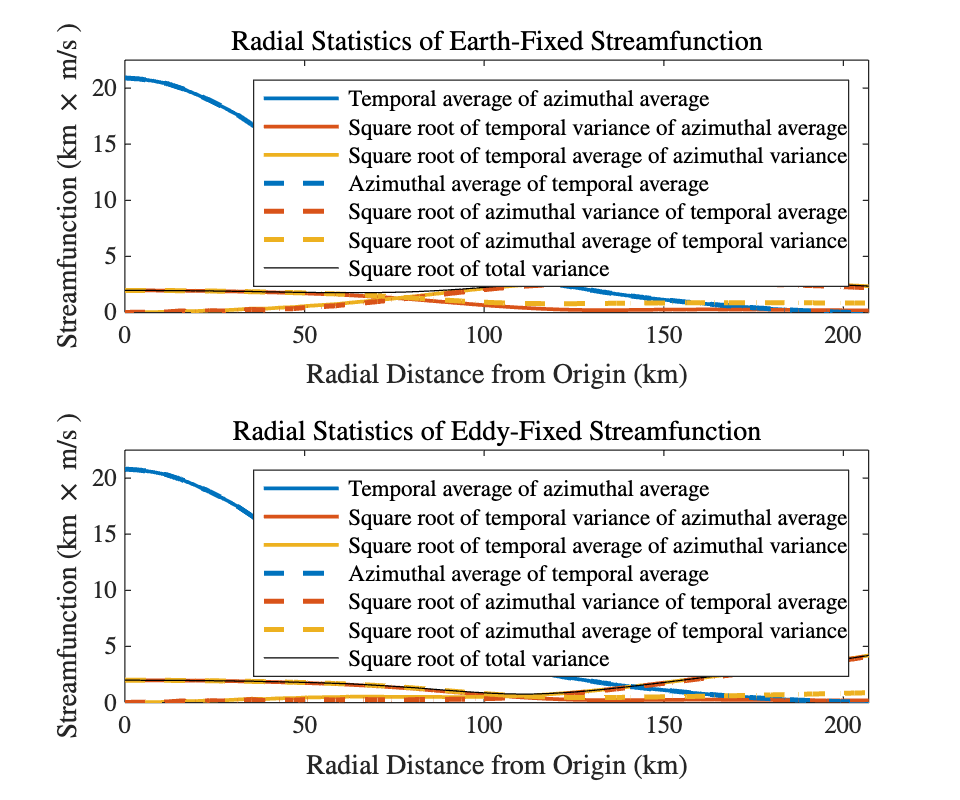

hf = figure();
hf.Position(3:4) = [1200, 1000];

tiledlayout(2,1);
nexttile

ha=plot(rmid,[mzEa stdz1Ea stdz2Ea],linewidth=1.5);hold on
ht=plot(rmid,[mzEt stdz1Et stdz2Et]);
hv=plot(rmid,sqrt(stdz1Et.^2+stdz2Et.^2),'k');
linestyle(ht(1),'2T--')
linestyle(ht(2),'2U--')
linestyle(ht(3),'2V--')
legend([ha;ht;hv],'Temporal average of azimuthal average',...
    'Square root of temporal variance of azimuthal average',...
    'Square root of temporal average of azimuthal variance',...
    'Azimuthal average of temporal average',...
    'Square root of azimuthal variance of temporal average',...
    'Square root of azimuthal average of temporal variance',...
    'Square root of total variance')

xlabel('Radial Distance from Origin (km)')
ylabel('Streamfunction (km $\times$ m/s )')
title('Radial Statistics of Earth-Fixed Streamfunction')
axis([0 max(rmid) 0 22.5])

nexttile

ha=plot(rmid,[mzea stdz1ea stdz2ea],linewidth=1.5);hold on
ht=plot(rmid,[mzet stdz1et stdz2et]);
hv=plot(rmid,sqrt(stdz1et.^2+stdz2et.^2),'k');
linestyle(ht(1),'2T--')
linestyle(ht(2),'2U--')
linestyle(ht(3),'2V--')
legend([ha;ht;hv],'Temporal average of azimuthal average',...
    'Square root of temporal variance of azimuthal average',...
    'Square root of temporal average of azimuthal variance',...
    'Azimuthal average of temporal average',...
    'Square root of azimuthal variance of temporal average',...
    'Square root of azimuthal average of temporal variance',...
    'Square root of total variance')

xlabel('Radial Distance from Origin (km)')
ylabel('Streamfunction (km $\times$ m/s )')
title('Radial Statistics of Eddy-Fixed Streamfunction')
axis([0 max(rmid) 0 22.5])

index = 1:50;

[mzEa,rmid,numzEa,stdz1Ea,stdz2Ea] = radialStatisticsFromField(xpE,ypE,psiE(:,:,index)/1000,firstAverage="azimuthal");
[mzEt,~,numzEt,stdz1Et,stdz2Et] = radialStatisticsFromField(xpE,ypE,psiE(:,:,index)/1000,firstAverage="temporal");
[mzea,~,numzea,stdz1ea,stdz2ea] = radialStatisticsFromField(xpe,ype,psipe(:,:,index)/1000,firstAverage="azimuthal");
[mzet,~,numzet,stdz1et,stdz2et] = radialStatisticsFromField(xpe,ype,psipe(:,:,index)/1000,firstAverage="temporal");

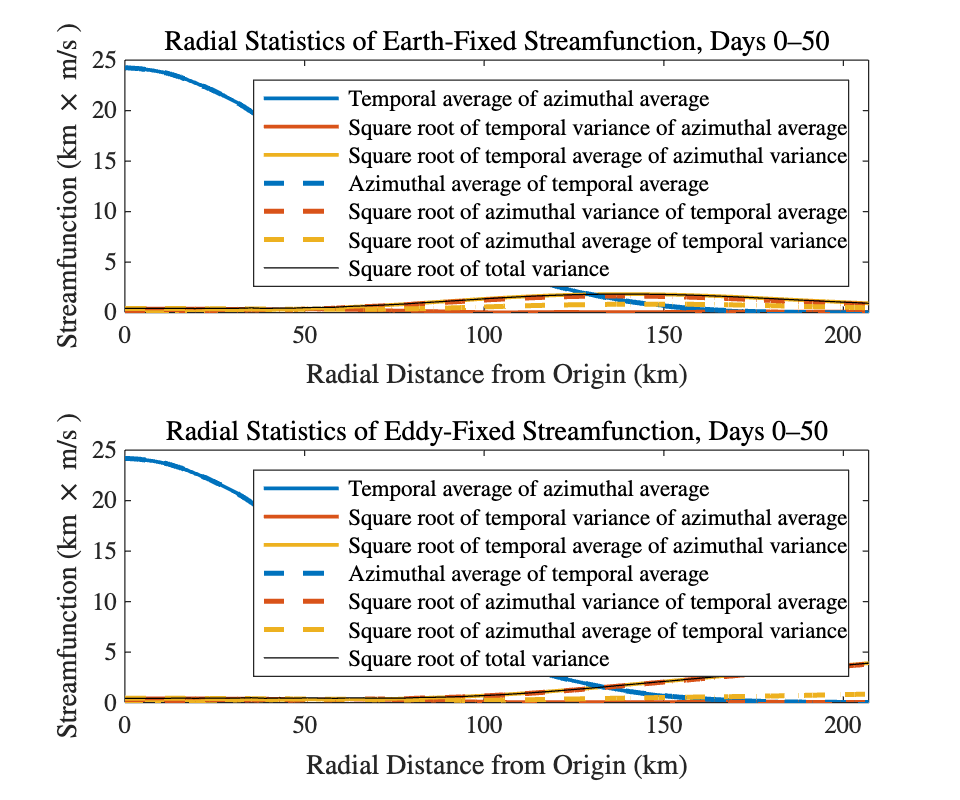

hf = figure();
hf.Position(3:4) = [1200, 1000];

tiledlayout(2,1);
nexttile

ha=plot(rmid,[mzEa stdz1Ea stdz2Ea],linewidth=1.5);hold on
ht=plot(rmid,[mzEt stdz1Et stdz2Et]);
hv=plot(rmid,sqrt(stdz1Et.^2+stdz2Et.^2),'k');
linestyle(ht(1),'2T--')
linestyle(ht(2),'2U--')
linestyle(ht(3),'2V--')
legend([ha;ht;hv],'Temporal average of azimuthal average',...
    'Square root of temporal variance of azimuthal average',...
    'Square root of temporal average of azimuthal variance',...
    'Azimuthal average of temporal average',...
    'Square root of azimuthal variance of temporal average',...
    'Square root of azimuthal average of temporal variance',...
    'Square root of total variance')

xlabel('Radial Distance from Origin (km)')
ylabel('Streamfunction (km $\times$ m/s )')
title('Radial Statistics of Earth-Fixed Streamfunction, Days 0--50')
axis([0 max(rmid) 0 25])

nexttile

ha=plot(rmid,[mzea stdz1ea stdz2ea],linewidth=1.5);hold on
ht=plot(rmid,[mzet stdz1et stdz2et]);
hv=plot(rmid,sqrt(stdz1et.^2+stdz2et.^2),'k');
linestyle(ht(1),'2T--')
linestyle(ht(2),'2U--')
linestyle(ht(3),'2V--')
legend([ha;ht;hv],'Temporal average of azimuthal average',...
    'Square root of temporal variance of azimuthal average',...
    'Square root of temporal average of azimuthal variance',...
    'Azimuthal average of temporal average',...
    'Square root of azimuthal variance of temporal average',...
    'Square root of azimuthal average of temporal variance',...
    'Square root of total variance')

xlabel('Radial Distance from Origin (km)')
ylabel('Streamfunction (km $\times$ m/s )')
title('Radial Statistics of Eddy-Fixed Streamfunction, Days 0--50')
axis([0 max(rmid) 0 25])

%Next, let's run a test that the scattered version of the code matches the
%gridded version... this should be coded into a test suite

[xpg,ypg] = meshgrid(xpE,ypE);
xpg = vrep(xpg,size(psiE,3),3);
ypg = vrep(ypg,size(psiE,3),3);
tg = vrep(permute([1:size(psiE,3)]',[3 2 1]),[size(xpg,1) size(xpg,2)],[1 2]);


tbin=0:0.5:366.5;

tic
[mza,rmid,numza,stdz1a,stdz2a] = radialStatisticsFromField(xpE,ypE,psipE,firstAverage="azimuthal");
[mzt,~,numzt,stdz1t,stdz2t] = radialStatisticsFromField(xpE,ypE,psipE,firstAverage="temporal");
toc

Elapsed time is 0.150877 seconds.



rbin=[-(rmid(2)-rmid(1))/2;rmid+(rmid(2)-rmid(1))/2];
%aresame(rmid,rmidS)
tic
[mzaS,rmidS,numzaS,stdz1aS,stdz2aS] = radialStatisticsFromScatter(xpg,ypg,tg,psipE,rbin,tbin,firstAverage="azimuthal");
[mztS,~,numztS,stdz1tS,stdz2tS] = radialStatisticsFromScatter(xpg,ypg,tg,psipE,rbin,tbin,firstAverage="temporal");
toc

Elapsed time is 0.223353 seconds.



aresame(mza,mzaS,1e-6)

ans = logical
   1


aresame(mzt,mztS,1e-6)

ans = logical
   1


aresame(stdz1a,stdz1aS,1e-6)

ans = logical
   1


aresame(stdz2a,stdz2aS,1e-6)

ans = logical
   1


aresame(stdz1t,stdz1tS,1e-6)

ans = logical
   1


aresame(stdz2t,stdz2tS,1e-6)

ans = logical
   1



%all tests pass